# Figure of PCC K vs S

Get the data for a figure bar plot with results of regularized permutation DFA for males and females separately

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'TmicAll7');
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UGroup = unique(TmicAll7);
Mat_PCC_mean = nan(2*(length(UGroup)+1),2);
Mat_PCC_std = nan(2*(length(UGroup)+1),2);
for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_MaleAcGroup%d.mat', GR)),  'PC_val_M', 'NPC_opt_M','PCC_males_mean_std', 'PCCperm_males_mean_std');
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_FemaleAcGroup%d.mat', GR)),  'PC_val_F', 'NPC_opt_F','PCC_females_mean_std', 'PCCperm_females_mean_std');
    NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
    NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
    Mat_PCC_mean(GR*2-1,1) = PCC_males_mean_std(NPC_opt_M_ind,1);
    Mat_PCC_mean(GR*2-1,2) = PCCperm_males_mean_std(NPC_opt_M_ind,1);
    Mat_PCC_mean(GR*2,1) = PCC_females_mean_std(NPC_opt_F_ind,1);
    Mat_PCC_mean(GR*2,2) = PCCperm_females_mean_std(NPC_opt_F_ind,1);
    Mat_PCC_std(GR*2-1,1) = PCC_males_mean_std(NPC_opt_M_ind,2);
    Mat_PCC_std(GR*2-1,2) = PCCperm_males_mean_std(NPC_opt_M_ind,2);
    Mat_PCC_std(GR*2,1) = PCC_females_mean_std(NPC_opt_F_ind,2);
    Mat_PCC_std(GR*2,2) = PCCperm_females_mean_std(NPC_opt_F_ind,2);
end

load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_MaleCalls.mat'), 'PC_val_M', 'NPC_opt_M','PCC_males_mean_std', 'PCCperm_males_mean_std')
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_FemaleCalls.mat'), 'PC_val_F', 'NPC_opt_F','PCC_females_mean_std', 'PCCperm_females_mean_std')
GR=8;
NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
Mat_PCC_mean(GR*2-1,1) = PCC_males_mean_std(NPC_opt_M_ind,1);
Mat_PCC_mean(GR*2-1,2) = PCCperm_males_mean_std(NPC_opt_M_ind,1);
Mat_PCC_mean(GR*2,1) = PCC_females_mean_std(NPC_opt_F_ind,1);
Mat_PCC_mean(GR*2,2) = PCCperm_females_mean_std(NPC_opt_F_ind,1);
Mat_PCC_std(GR*2-1,1) = PCC_males_mean_std(NPC_opt_M_ind,2);
Mat_PCC_std(GR*2-1,2) = PCCperm_males_mean_std(NPC_opt_M_ind,2);
Mat_PCC_std(GR*2,1) = PCC_females_mean_std(NPC_opt_F_ind,2);
Mat_PCC_std(GR*2,2) = PCCperm_females_mean_std(NPC_opt_F_ind,2);


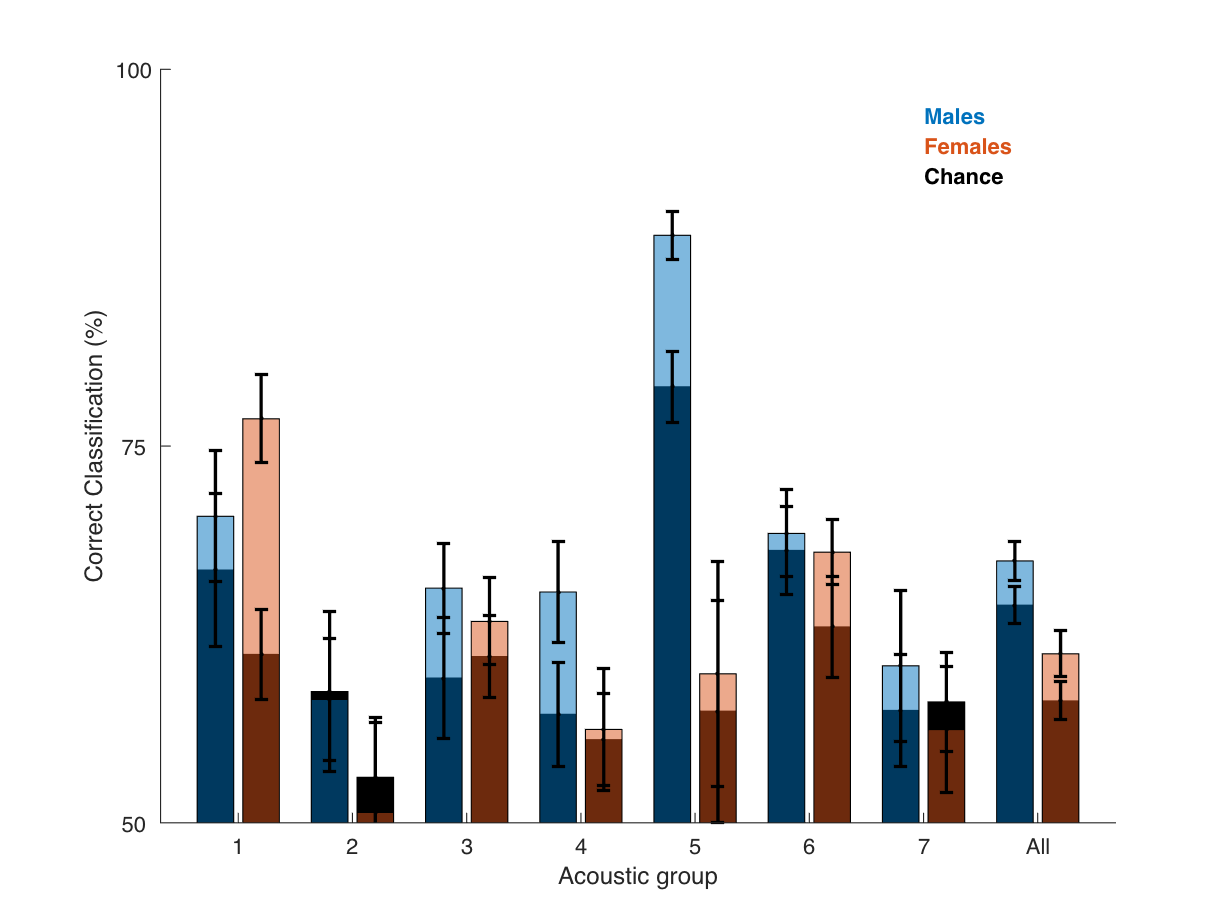


figure()
GR = length(UGroup);
X = reshape([1:GR+1; 1:GR+1] + repmat([-0.2;0.2], 1, GR+1), 1,(GR+1)*2);
bar(X,Mat_PCC_mean(:,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(:,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat([ColorCode(1,:); ColorCode(2,:)],8,1);
hold on
errorbar(X,Mat_PCC_mean(:,2),Mat_PCC_std(:,2), Mat_PCC_std(:,2), 'k.','LineWidth',1.5)
hold on
errorbar(X,Mat_PCC_mean(:,1),Mat_PCC_std(:,1), Mat_PCC_std(:,1), 'k.','LineWidth',1.5)
ylim([50 100])
box off
ylabel('Correct Classification (%)')
xlabel('Acoustic group')
XTL = get(gca,'XTickLabel');
XTL{end} = 'All';
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
text(7,97,'Males','color',ColorCode(1,:), 'FontWeight','bold')
hold on
text(7,95,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')
hold on
text(7,93,'Chance','color','k', 'FontWeight', 'bold')
hold off

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'TmicAll7');
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UGroup = unique(TmicAll7);
Mat_PCC_mean = nan((length(UGroup)+1),2);
Mat_PCC_std = nan((length(UGroup)+1),2);
for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_AcGroup%d.mat', GR)),  'PC_val', 'NPC_opt_all','PCC_all_mean_std', 'PCCperm_all_mean_std');
    NPC_opt_ind = find(PC_val==NPC_opt_all);
    Mat_PCC_mean(GR,1) = PCC_all_mean_std(NPC_opt_ind,1);
    Mat_PCC_mean(GR,2) = PCCperm_all_mean_std(NPC_opt_ind,1);
    Mat_PCC_std(GR,1) = PCC_all_mean_std(NPC_opt_ind,2);
    Mat_PCC_std(GR,2) = PCCperm_all_mean_std(NPC_opt_ind,2);
end

load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_AllCalls.mat'), 'PC_val', 'NPC_opt_all','PCC_all_mean_std', 'PCCperm_all_mean_std')
GR=8;
NPC_opt_ind = find(PC_val==NPC_opt_all);
Mat_PCC_mean(GR,1) = PCC_all_mean_std(NPC_opt_ind,1);
Mat_PCC_mean(GR,2) = PCCperm_all_mean_std(NPC_opt_ind,1);
Mat_PCC_std(GR,1) = PCC_all_mean_std(NPC_opt_ind,2);
Mat_PCC_std(GR,2) = PCCperm_all_mean_std(NPC_opt_ind,2);


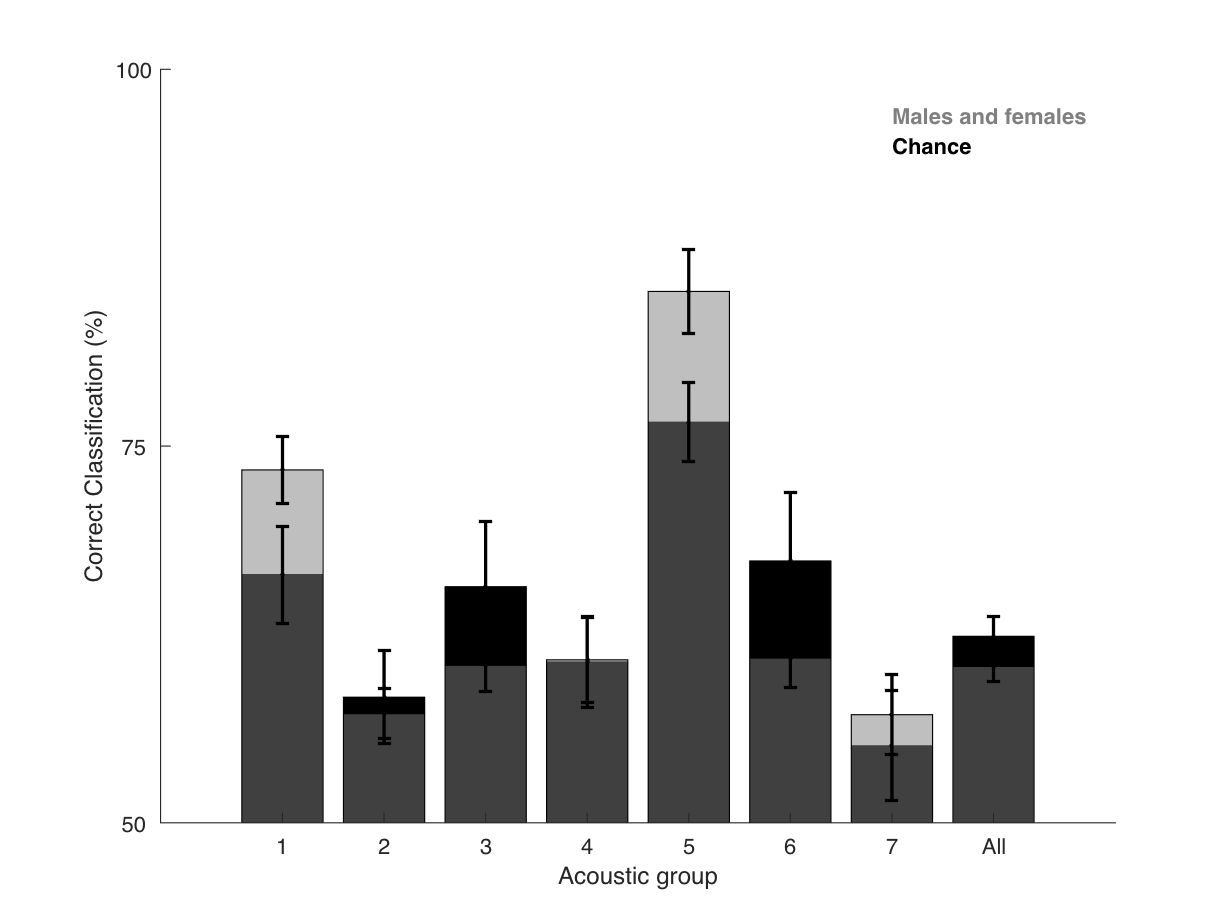


figure()
GR = length(UGroup);
X = 1:GR+1;
bar(X,Mat_PCC_mean(:,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(:,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat([0.5 0.5 0.5],8,1);
hold on
errorbar(X,Mat_PCC_mean(:,2),Mat_PCC_std(:,2), Mat_PCC_std(:,2), 'k.','LineWidth',1.5)
hold on
errorbar(X,Mat_PCC_mean(:,1),Mat_PCC_std(:,1), Mat_PCC_std(:,1), 'k.','LineWidth',1.5)
ylim([50 100])
box off
ylabel('Correct Classification (%)')
xlabel('Acoustic group')
XTL = get(gca,'XTickLabel');
XTL{end} = 'All';
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
hold on
text(7,97,'Males and females','color',[0.5 0.5 0.5], 'FontWeight', 'bold')
hold on
text(7,95,'Chance','color','k', 'FontWeight', 'bold')
hold off